close all; clc

% find equilibrium points
syms a positive
syms b nonzero
syms x1 x2

% find equilibrium points
h = x2/(1+x1);
f1 = (1 - x1 - 2*h)*x1;
f2 = (2-h)*x2;

sln = solve([f1==0, f2==0], [x1 x2]);
sln.x1

$$ans = \left(\begin{array}{c} 0\\ 1\\ 0\\ -3 \end{array}\right)$$

sln.x2

$$ans = \left(\begin{array}{c} 0\\ 0\\ 2\\ -4 \end{array}\right)$$

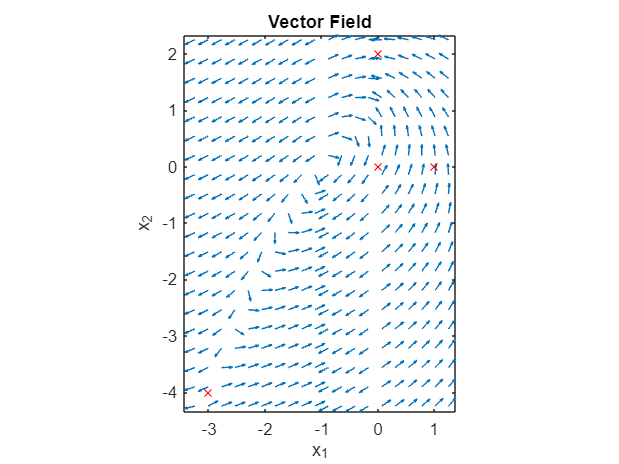


% Create vector field
x = linspace(-3.25,1.25,20);
y = linspace(-4.25,2.25,20);
[X,Y] = meshgrid(x,y);

H = Y./(1+X);
DX = (1 - X - 2.*H).*X;
DY = (2-H).*X;

N = sqrt(DX.^2 + DY.^2);
quiver(X,Y,DX./N,DY./N,0.5);
xlabel('x_1')
ylabel('x_2')
axis tight equal;
title("Vector Field")

% draws x's on the equilibrium points
hold on;
for i=1:numel(sln.x1)
    if isreal(sln.x1(i)) && isreal(sln.x2(i))
        plot(sln.x1(i), sln.x2(i), 'rx')
    end
end
hold off